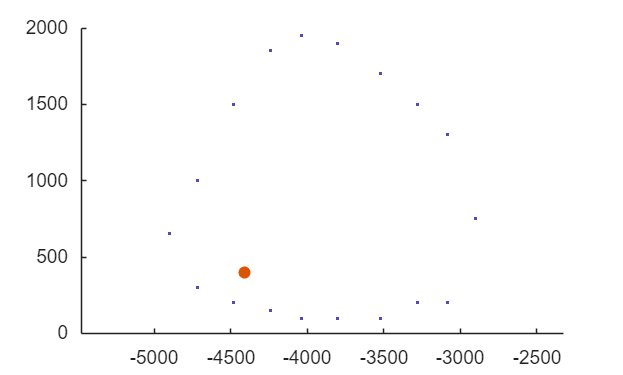

fig = figure;
clf(fig);
hold on;
% plot(SCborder.lowerX, SCborder.lowerY, ...
%     'LineWidth', 1.5, 'Marker', '.', 'Color', [0.32 0.29 0.72]);
% plot(SCborder.upperX, SCborder.upperY, ...
%     'LineWidth', 1.5, 'Marker', '.', 'Color', [0.32 0.29 0.72]);
scatter(-SCborder.x_new__m_, SCborder.y_new__m_, 20, [0.32 0.29 0.72], '.');
sc_axon = [-4410, 398];
scatter(sc_axon(1), sc_axon(2), 'filled');

ylim([0, 2000]);
xlim([-5000, -2500]);
axis equal;
hold off;

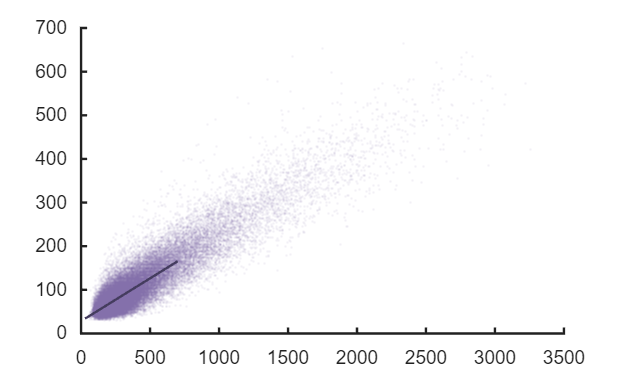

model1 = fitlm(axon1065.c1, axon1065.c2);
slope =table2array(model1.Coefficients(2,1));
intercept= model1.Coefficients.Estimate(1);
fig = figure;
clf(fig);
hold on;
color = [68, 60, 94]/255;
lighta = [123, 111, 163]/255;
lightb = [112, 128, 175]/255;
scatter(axon1065.c1, axon1065.c2, 10, '.', ...
    'MarkerEdgeColor',lighta, 'MarkerEdgeAlpha',0.1);
x = [min(axon1065.c2); 700];
y = slope*x + intercept;
plot(x(:), y(:), 'Color',color, 'LineWidth',1.2);
ax = gca;
ax.LineWidth = 1.2;

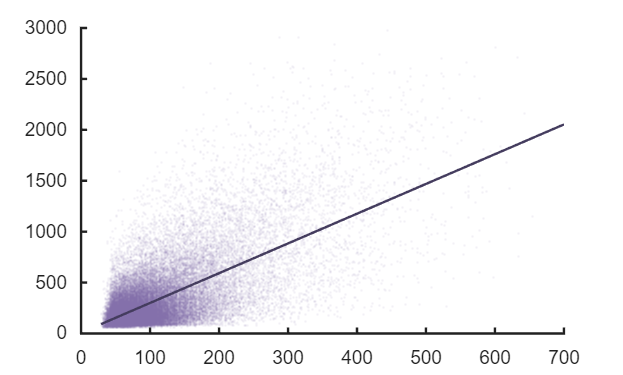

model1 = fitlm(axon1065.c2, axon1065.c3);
slope =table2array(model1.Coefficients(2,1));
intercept= model1.Coefficients.Estimate(1);
fig = figure;
clf(fig);
hold on;
color = [68, 60, 94]/255;
lighta = [123, 111, 163]/255;
lightb = [112, 128, 175]/255;
scatter(axon1065.c2, axon1065.c3, 10, '.', ...
    'MarkerEdgeColor',lighta, 'MarkerEdgeAlpha',0.1);
x = [min(axon1065.c2); 700];
y = slope*x + intercept;
plot(x(:), y(:), 'Color',color, 'LineWidth',1.2);
ax = gca;
ax.LineWidth = 1.2;

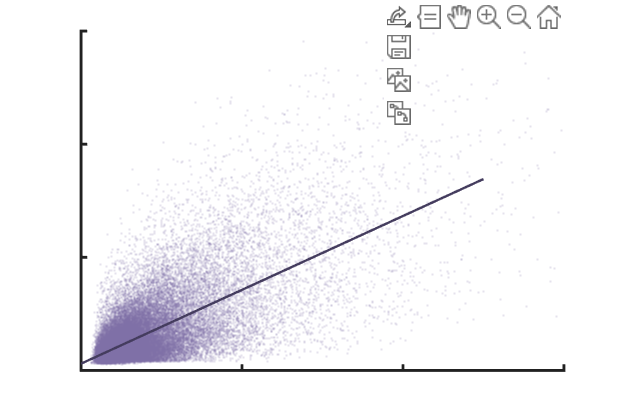

model2 = fitlm(axon1065.c1, axon1065.c3);
slope =table2array(model2.Coefficients(2,1));
intercept= model2.Coefficients.Estimate(1);
fig = figure;
fig.Position=[100  100  600  400];
clf(fig);
hold on;
color = [68, 60, 94]/255;
lighta = [123, 111, 163]/255;
lightb = [112, 128, 175]/255;
scatter(axon1065.c1, axon1065.c3, 10, '.', ...
    'MarkerEdgeColor',lighta, 'MarkerEdgeAlpha',0.2);
x = [0; 2500];
y = slope*x + intercept;
plot(x(:), y(:), 'Color',color, 'LineWidth',1.2);
ax = gca;
ax.LineWidth = 1.4;
xlim(ax, [0, 3000]);
ylim(ax, [0, 3000]);
yticks(ax, [0, 1000, 2000, 3000]);
xticks(ax, [0, 1000, 2000, 3000]);
xticklabels(ax, []);
yticklabels(ax, []);
%axis equal;
hold off;

%summary bad but I have to do
allmatch = fetch(proj(sln_cell.Cell, 'cell_unid') * ...
    proj(sln_cell.CellAxonMatch,'cell_unid', 'axon_id') * sln_cell.Axon, '*');
celltypes = {};
for i = 1:numel(allmatch)
    celltypes{end+1} = sln_cell.AssignType.fetch_current_type(allmatch(i).cell_unid);
end

t= struct2table(allmatch);
t.cell_type = celltypes';

writetable(t, 'match_sum.csv');

T = readtable('match_sum.csv');
cellTypes = unique(T.cell_type);      % rows
% regions   = unique(T.brain_region);   % cols

% % Map each row to its (cellType, region) index
% [~, ri] = ismember(T.cell_type, cellTypes);
% [~, ci] = ismember(T.brain_region, regions);

% Joint count matrix
regions = ["SCs"; "dLGN"; "vLGN"; "NOT"; "OPN"];   % your desired order
[~, ci] = ismember(T.brain_region, regions);
M = accumarray([ri ci], 1, [numel(cellTypes) numel(regions)]);

% Labeled table for inspection
counts = array2table(M, 'RowNames', cellTypes, 'VariableNames', regions);
disp(counts);

                                           SCs    dLGN    vLGN    NOT    OPN
                                           ___    ____    ____    ___    ___

    F-mini-ON                               0      0       1       0      0 
    OFF horizontal OS - symmetric           1      0       1       0      0 
    OFF medium sustained                    1      0       0       0      0 
    OFF sustained EW1no                     1      0       0       0      0 
    OFF transient small RF                  0      0       0       0      1 
    ON DS sustained - direction unknown     1      2       0       0      0 
    ON alpha                                1      2       0       0      1 
    ON bu

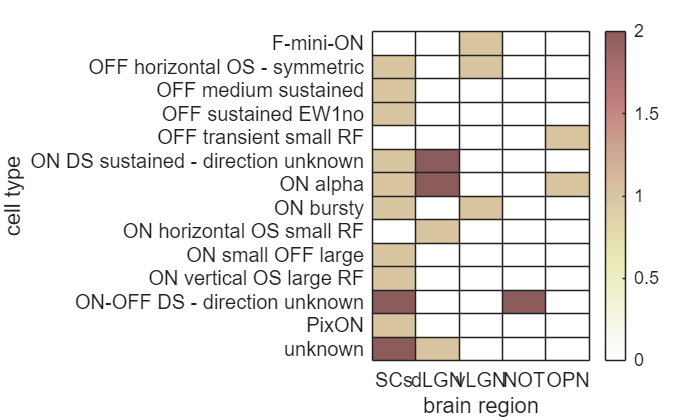

% h = heatmap(dist_pre);
% h.Colormap = flipud(copper);
% h.CellLabelColor = 'none';
% saveas(gcf, 'prediction_dist_heat.svg');
% Heatmap
figure;
h = heatmap(regions, cellTypes, M);
xlabel('brain region'); 
ylabel('cell type');
cmap = pink(256);
cmap = cmap(50:end, :);   % discard the darkest ~20% (rows 1–49)

h.Colormap =flipud(cmap);
h.CellLabelColor = 'none';
saveas(gcf, 'summarymatch.svg');